# MATLABの画像処理機能による

# 印象派モネの各時代の作品で変化する要素の分析

### 所属クラス：C3, 氏名：山野 元久, 学籍番号：s1320112

## 1. 導入(Introduction)

　クロード・モネ(Claude Monet)は19, 20世紀にかけて活躍した印象派を代表する画家である[1]。人間の視界に一瞬映る眩さの繊細な描写を絵画に写すことに注力していた。モネの緻密な光の表現は専ら彼がその生涯で描いた風景画によく現れている。そこで、私はモネが得意とした明るさを絵画で表現する技法が時代を通じてどのように変遷していったかを知りたい。各ウェブサイトよりダウンロードした各時代に制作されたモネの風景画作品を5点、MATLABにインポートし画像処理をかけ、各時代の作品が持つ共通点や相違点を解明する。

## 2. データ(Data)

　この研究の為に用いたモネ作品の画像データの詳細は以下の通りである。

*　１．Impression, Sunrise(1872)*

　　　Site：Wikimedia Commons

　　　URL：https://commons.wikimedia.org/wiki/File:Monet_-_Impression,_Sunrise.jpg

　　　Copy Right：Claude Monet, Public domain, via Wikimedia Commons

　　　参照日：2025年11月28日

　　　Size：5773*4478px

*　２．The Saint-Lazare Station(1877)*

　　　Site：Wikimedia Commons

　　　URL：https://commons.wikimedia.org/wiki/File:Claude_Monet_-_The_Saint-Lazare_Station_-_Google_Art_Project.jpg

　　　Copy Right：Claude Monet, Public domain, via Wikimedia Commons

　　　参照日：2025年11月28日

　　　Size：3708*2757px

*　３．Rouen Cathedral, West Facade(1894)*

　　　Site：National Gallery of Art

　　　URL：https://www.nga.gov/artworks/46524-rouen-cathedral-west-facade

　　　Copy Right：Creative Commons Zero (CC0)

　　　参照日：2025年11月28日

　　　Size：2683*4096px

*　４．The Japanese Footbridge(1899)*

　　　Site：National Gallery of Art

　　　URL：https://www.nga.gov/artworks/74796-japanese-footbridge

　　　Copy Right：Creative Commons Zero (CC0)

　　　参照日：2025年11月28日

　　　Size：4096*3302px

*　５．Water Lilies(1915)*

　　　Site：Wikimedia Commons

　　　URL：https://commons.wikimedia.org/wiki/File:Claude_Monet_-_Seerosen.jpg

　　　Copy Right：Claude Monet, Public domain, via Wikimedia Commons

　　　参照日：2025年11月28日

　　　Size：3704*2745px

　　　※本来の睡蓮は部屋の一面を覆うようなパノラマ画としてできている。ここで使っているのは絵画の一部を長方形に切り取ったもの。

　これらの画像ファイルをまとめて圧縮したMonet.zipをMATLABに読み込んだ上で作業を行う。

## 3. 手法(Method)

　手法においては大きく分けて3つの方向性で絵画を分析したい。初めに、画像を二値化した上で白と黒の面積比や光と影の全体的な構図を観察する。2つ目に、画像をHSV形式へと変換したうえで、彩度と光度の平均値の推移を見る。最後に、RGB方式の画像を、K分類法を用いて画像を4つのの領域ごとに分割、各絵画の特徴を把握する。

#### 3.0. 画像のインポート

　まず、インポートしたMonet.zipを解凍する。

%unzip Monet.zip
% 実行するのは一回で良いため、コメントアウトしておく。

　得られた5枚の画像をimread()によって読み込む。得られた画像をsubplot()とimshow()によって確かめる。(授業で習得したimshowpair()では3枚以上の画像を取り扱えない為。)

%imread()による画像の読み込み。
im_sunrise = imread("Impression_Sunrise.jpg");
im_station = imread("Saint_Lazare_Station.jpg");
im_rouen = imread("Rouen_Cathedral_West_Facade.jpg");
im_bridge = imread("The_Japanese_Footbridge.jpg");
im_lilies = imread("Water_Lilies.jpg");

%Extra Code
%imageの行列をセル行列で。タイトルをそのまま一次元の配列とした。
image_list = {im_sunrise, im_station, im_rouen, im_bridge, im_lilies};
image_title = ["Impression, Sunrise", "The Saint-Lazare Station", "Rouen Cathedral, WF", "The Japanese Footbridge", "Water Lilies"]

image_title = 1×5 string array
    "Impression, Sunrise"    "The Saint-Lazare Station"    "Rouen Cathedral, WF"    "The Japanese Footbridge"    "Water Lilies"


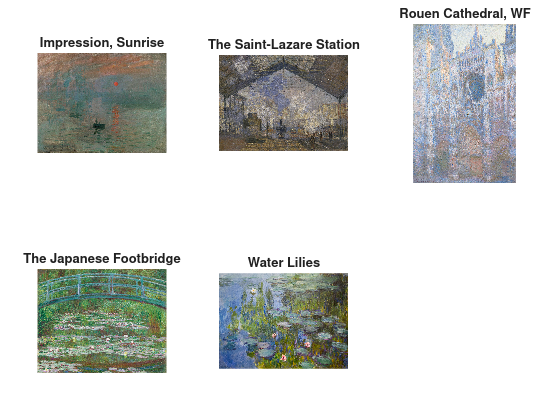



%画像の表示。
figure;
t1 = tiledlayout(2,3, 'Padding', 'compact');
%%nexttile;  imshow(im_sunrise);  title("Impression, Sunrise");  
%%nexttile;  imshow(im_station);  title("The Saint-Lazare Station");  
%%nexttile;  imshow(im_rouen);  title("Rouen Cathedral, WF");  
%%nexttile;  imshow(im_bridge);  title("The Japanese Footbridge"); 
%%nexttile;  imshow(im_lilies);  title("Water Lilies");  
%ExtraCode
for i =1:length(image_list)
    nexttile;
    imshow(image_list{i});
    title(image_title(i));
end

#### 3.1. 画像のグレースケール、バイナリ化による分析

　　　画像をバイナリ化するにあたって、im2gray()を用い、色を排除する。グレースケール画像に対し、histogram()を用いて画像の輝度分布を調べる。(元々imhistでやるつもりだったが、imhistとtiledlayoutを同時使用するとエラーが出たためhistogram()にした。)

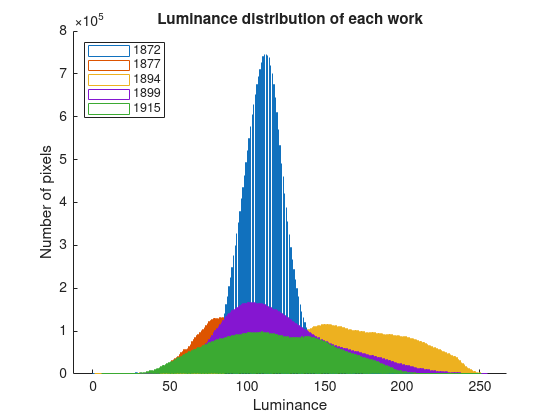

%グレースケールのコード。
%%gs_sunrise = im2gray(im_sunrise);
%%gs_station = im2gray(im_station);
%%gs_rouen = im2gray(im_rouen);
%%gs_bridge = im2gray(im_bridge);
%%gs_lilies = im2gray(im_lilies);

%Extra Code
gs_list = cell(1:5);
for i = 1:length(image_list)
    gs_list{i} = im2gray(image_list{i});
end

%輝度分布。
figure;
hold on
%Extra Code
%%histogram(gs_sunrise,'DisplayStyle', 'stairs'); 
%%histogram(gs_station,'DisplayStyle', 'stairs'); 
%%histogram(gs_rouen,'DisplayStyle', 'stairs'); 
%%histogram(gs_bridge,'DisplayStyle', 'stairs');
%%histogram(gs_lilies,'DisplayStyle', 'stairs'); 
for i = 1:length(image_list)
    histogram(gs_list{i},'DisplayStyle', 'stairs');
end
title("Luminance distribution of each work");
xlabel("Luminance"); 
ylabel("Number of pixels");
legend('1872','1877', '1894','1899','1915','Location','northwest');
hold off

得た画像をimbinarize()によって二値化し、表示する。0と1を分ける基準となる閾値は0.5に設定する。

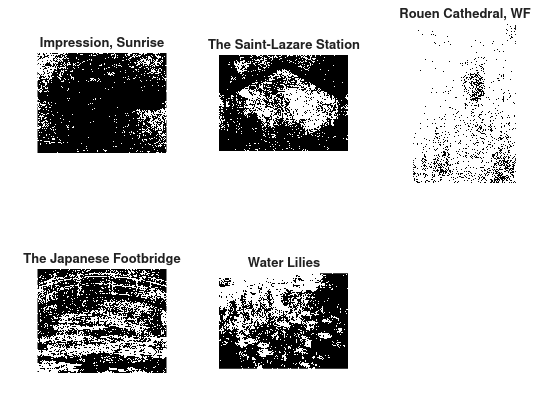

%二値化のコード。
threshold = 0.5;
%%bw_sunrise = imbinarize(gs_sunrise, threshold);
%%bw_station = imbinarize(gs_station, threshold);
%%bw_rouen = imbinarize(gs_rouen, threshold);
%%bw_bridge = imbinarize(gs_bridge, threshold);
%%bw_lilies = imbinarize(gs_lilies, threshold);

%Extra Code
bw_list = cell(1, 5);
for i = 1:length(gs_list)
    bw_list{i} = imbinarize(gs_list{i}, threshold);    
end

%画像の表示。
figure;
t3 = tiledlayout(2,3, 'Padding', 'compact');
%%nexttile;  imshow(bw_sunrise);  title("Impression, Sunrise");  
%%nexttile;  imshow(bw_station);  title("The Saint-Lazare Station");
%%nexttile;  imshow(bw_rouen);  title("Rouen Cathedral, West Facade");  
%%nexttile;  imshow(bw_bridge);  title("The Japanese Footbridge"); 
%%nexttile;  imshow(bw_lilies);  title("Water Lilies"); 
%Extra Code
for i =1:length(bw_list)
    nexttile;
    imshow(bw_list{i});
    title(image_title(i));
end

バイナリ化した画像の全体に占める白の割合を算出し、棒グラフとしてプロットする。

ratio = zeros(1, 5);
years = [1872 1877 1894 1899 1915];

%%ratio(1) = (nnz(bw_sunrise) / numel(bw_sunrise))*100;
%%ratio(2) = (nnz(bw_station) / numel(bw_station))*100;
%%ratio(3) = (nnz(bw_rouen) / numel(bw_rouen))*100;
%%ratio(4) = (nnz(bw_bridge) / numel(bw_bridge))*100;
%%ratio(5) = (nnz(bw_lilies) / numel(bw_lilies))*100;

%Extra Code
for i = 1:length(ratio)
    ratio(i) = (nnz(bw_list{i}) / numel(bw_list{i})) * 100;
end

disp(ratio);

   11.8524   26.8296   90.3300   37.3507   38.3808



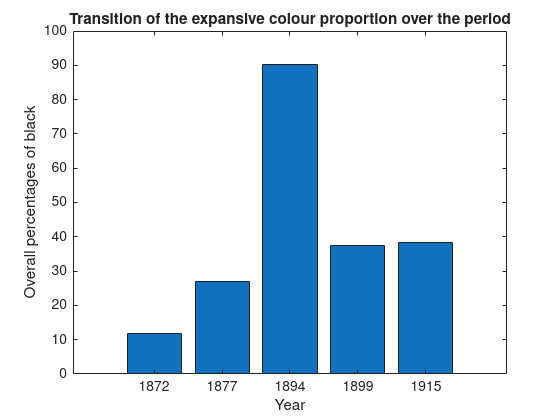

figure;
bar(1:length(years), ratio);
xticks(1:length(years));
xticklabels(string(years));
xlabel("Year");
ylabel("Overall percentages of black")
title("Transition of the expansive colour proportion over the period");

加えて、bwconncomp()によって連続的に繋がっている白の領域を検出し、その特徴を観察する。

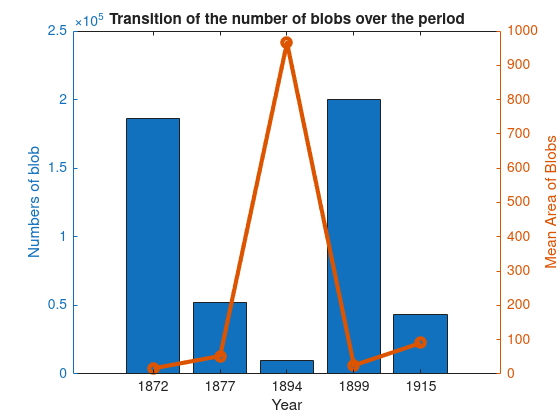

%%cc_sunrise = bwconncomp(bw_sunrise);
%%cc_station = bwconncomp(bw_station);
%%cc_rouen = bwconncomp(bw_rouen);
%%cc_bridge = bwconncomp(bw_bridge);
%%cc_lilies = bwconncomp(bw_lilies);
%%CC = [cc_sunrise cc_station cc_rouen cc_bridge cc_lilies];

%Extra Code
CC = cell(1, 5);
for i = 1:length(bw_list)
    CC{i} = bwconncomp(bw_list{i});
end

%%stats_sunrise = regionprops(cc_sunrise, 'Area');
%%stats_station = regionprops(cc_station, 'Area');
%%stats_rouen = regionprops(cc_rouen, 'Area');
%%stats_bridge = regionprops(cc_bridge, 'Area');
%%stats_lilies = regionprops(cc_lilies, 'Area');
%%stats_list = {stats_sunrise, stats_station, stats_rouen, stats_bridge, stats_lilies};

%Extra Code
stats_list = cell(1, 5);
for i = 1:length(CC)
   stats_list{i} = regionprops(CC{i}, 'Area');
end

cc_numbers = cellfun(@(c) c.NumObjects, CC);
Stats_area = cellfun(@(a) mean([a.Area]), stats_list);

f = figure;

yyaxis left;
bar(1:length(years), cc_numbers);
xticks(1:length(years));
xticklabels(string(years));
xlabel("Year");
ylabel("Numbers of blob")
title("Transition of the number of blobs over the period");
hold on

yyaxis right;
plot(1:length(years), Stats_area, '-o', 'LineWidth', 3);
ylabel("Mean Area of Blobs");
hold off
img = getframe(gca);

imwrite(img.cdata, 'blobgraph.png');

#### 3.2. HSV変換による分析

　　　取り込んだ画像は全て、RGBによる3次元の配列によって定義されている。ここでは、全ての画像をHSV(色相、彩度、明度)の形式に変る。その上で、各作品の平均彩度と平均明度を調べ、棒グラフで比較する。

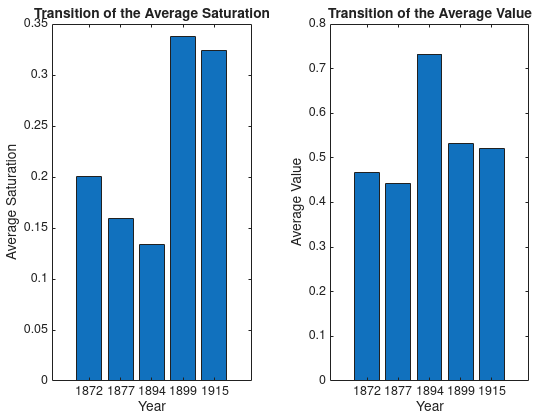

%RGB画像をHSV画像に変換
%%hsv_sunrise = rgb2hsv(im_sunrise);
%%hsv_station = rgb2hsv(im_station);
%%hsv_rouen = rgb2hsv(im_rouen);
%%hsv_bridge = rgb2hsv(im_bridge);
%%hsv_lilies = rgb2hsv(im_lilies);

%%sat = [mean(hsv_sunrise(:,:,2), "all") mean(hsv_station(:,:,2), "all") mean(hsv_rouen(:,:,2), "all") mean(hsv_bridge(:,:,2), "all") mean(hsv_lilies(:,:,2), "all")];
%%val = [mean(hsv_sunrise(:,:,3), "all") mean(hsv_station(:,:,3), "all") mean(hsv_rouen(:,:,3), "all") mean(hsv_bridge(:,:,3), "all") mean(hsv_lilies(:,:,3), "all")];

%Extra Code
sat = zeros(1,5);
val = zeros(1,5);
hsv_list = cell(1,5);
for i = 1:length(image_list)
    hsv_list{i} = rgb2hsv(image_list{i});
    sat(i) = mean(hsv_list{i}(:,:,2), "all");
    val(i) = mean(hsv_list{i}(:,:,3), "all");
end

%彩度と明度の平均を分布として表示させる。
figure;
t4 = tiledlayout(1,2, 'Padding', 'compact');

nexttile;
bar(1:length(years), sat);
xticks(1:length(years));
xticklabels(string(years));
xlabel("Year");
ylabel("Average Saturation")
title("Transition of the Average Saturation");

nexttile;
bar(1:length(years), val);
xticks(1:length(years));
xticklabels(string(years));
xlabel("Year");
ylabel("Average Value")
title("Transition of the Average Value");

#### 3.3. K分類法による分析

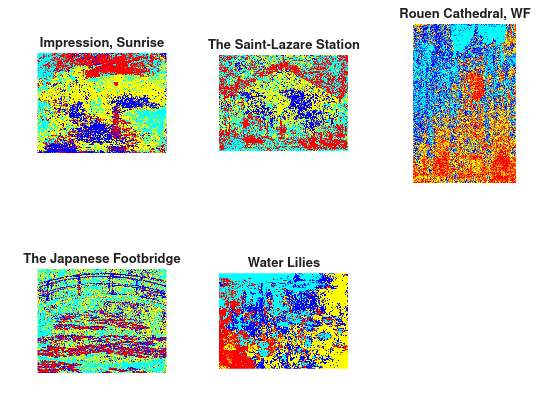

%分割するクラスkを設定し、imsegkmeans()によりK分類を行う。
k = 4;
%%[L1, C1] = imsegkmeans(single(im_sunrise), k);
%%[L2, C2] = imsegkmeans(single(im_station), k);
%%[L3, C3] = imsegkmeans(single(im_rouen), k);
%%[L4, C4] = imsegkmeans(single(im_bridge), k);
%%[L5, C5] = imsegkmeans(single(im_lilies), k);

%Extra Code
L = cell(1,5);
C = cell(1,5);
for i = 1:length(image_list)
    [L{i}, C{i}] = imsegkmeans(single(image_list{i}),k);
end

%4つの色に分けた画像を表示させる。
figure;
t5 = tiledlayout(2,3, 'Padding', 'compact');

%%nexttile;  imshow(label2rgb(L1));  title("Impression, Sunrise");  
%%nexttile;  imshow(label2rgb(L2));  title("The Saint-Lazare Station");  
%%nexttile;  imshow(label2rgb(L3));  title("Rouen Cathedral, WF");  
%%nexttile;  imshow(label2rgb(L4));  title("The Japanese Footbridge"); 
%%nexttile;  imshow(label2rgb(L5));  title("Water Lilies"); 

%Extra Code
for i = 1:length(L)
    nexttile;
    imshow(label2rgb(L{i}));
    title(image_title(i));
end

　　　各クラスタにおける平均のRGB値がC1~C5に格納されているため、それらクラスタの中心間の距離を図ることで、各画像に置けるクラスごとの色のばらつきを評価したい。

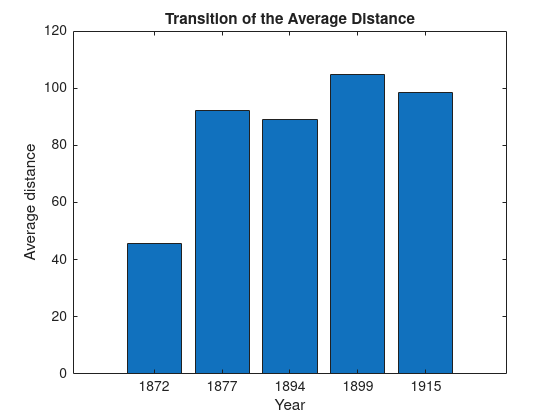

%%dist = [mean(pdist(C1)) mean(pdist(C2)) mean(pdist(C3)) mean(pdist(C4)) mean(pdist(C5))];
%Extra Code
dist = cellfun(@(c) mean(pdist(c)), C);

figure;
bar(1:length(years), dist);
xticks(1:length(years));
xticklabels(string(years));
xlabel("Year");
ylabel("Average distance")
title("Transition of the Average Distance");

## 4. 結果(Result)

　各観点から調べたデータの全体的な傾向として、時代が進むにつれて完全な比例関係を保ちながら変化していく項目は存在しなかった。しかし、得られた個々のデータを観察すると一定の方向性を掴むことができる。

　3.1.より、グレスケール化した画像の輝度をヒストグラムによって確かめたところ、青い領域によって表示されている1872年の作品は輝度が100~120前後に集中し、極端な分布をしている。それ以降の作品は、特定の輝度にピクセルが集中する事は無く全て2*10^5以下の値を取っている。1877年、1894年の作品はなだらかな山なりの分布をしている。1894年と1915年の作品は分布が正規分布のようにはっきりとした山形にならず、分布が平滑でない。

　また、2値化した画像を基に白と黒の面積比を比較したグラフによると、1894年の作品が特に白色の割合が多いことが分かる。1894年の作品を除いたとき、他の作品は時代が進むにつれて、黒の割合が増えていることが分かる。1872年に10%程だったが、1915年で最終的に40%近くまで到達している。

　その次の棒グラフでは、bwconncomp()より白色で繋がっている領域(Blob)を検出し、各画像における総数と平均的な面積を算出した。これによると、Blobの数は1872年と1899年が押しなべて高く、1894年が最も少ない。Blobの平均面積においては、1894年の作品が突出して高く1000に近い。一方で、他の作品は0~100の間である。

　画像をHSVに変換し、画像の平均彩度と平均明度を算出、棒グラフによって比較した。平均彩度は、1872年~1894年の前半3作品と、1899年、1915年の後半2作品で明確に別れている。前半の作品は0~1の値を取る彩度の内、0.2~0.1に留まっており、1872年、1877年、1894年と順々に減少している。後半の2作品は両方とも彩度0.3以上を保っている。1899年から1915年で平均彩度は僅かに減少した。平均明度は、1894年の作品が特に高く0.7を超えている。一方で、他の作品は0.4~0.6の間を取っている。

　最後に、K分類によって色に基づき4つのパーツにグルーピングし、各クラスタの中心間の距離を図ることでどれだけ類似した色がバラバラに配置されているのかを調べた。その結果、1872年の作品が約40で特に低い値をとった。1877年~1915年の作品は100前後の値を取っている。

## 5. 議論/考察(Discuss)

　このような結果が出た要因について考察する。

#### 　5.1. *Impression, Sunrise(1872), The Saint-Lazare Station(1877)*

*　Impression, Sunrise(1872)の*絵画の特徴的な部分は、他の作品と比べ限定的な輝度によって描かれたことや、K分類による分析で判明した大雑把な色のばらつきが少ないという点にある。これは、モネが日光に反射する水面の景色を書く際に、まだ光の強度の差異をまだ厳密に表現しきれていなかった為なのではと考える。

　*The Saint-Lazare Station(1877)*では、蒸気機関車から出る煙が人の目にどのように映るのかを意識して描かれている。各グラフにおいて、この作品が取る値は際立った値を取ることなく、棒グラフでは他作品と類似する部分が強くみられる。私はこの時に、モネが得意とする非物体の表現技法の型がある程度定まったのではないかと考える。

#### 　5.2. *Rouen Cathedral, West Facade(1894)*

　この作品の特筆する部分は、比較的高い輝度、明度を持つこと、二値化した際にも白い部分が絵の大半を占めること、またその白部分の領域が一つにまとまっていること等が上げられる。取り扱った5作品の内でイレギュラーな結果を多く出した。私はその原因は、この作品が連作として描かれたためだと考えられる。モネの連作は基本的に光の条件（朝日、昼間、夜の月光etc...）を変えて同じ被写体を描き上げている。すると、作品の1部のみを検証に用いてしまったため、他の作品とよりも特殊なタッチであることが目立ってしまったと考えられる。

#### 　5.3. *The Japanese Footbridge(1899), Water Lilies(1915)*

　この後期の2作品はグラフによって可視化したデータにおいても共通する項目が多い。特に彩度において両作品が0.3以上を取っているように、この時期から黒色白色のような要素が無くなってきているように感じ取れる。一方で、1915年の作品は輝度の分布が山型になっておらず、崩れている。この輝度の分布が変化した原因はモネが患った白内障の影響ではないかと考える。モネは、1912年に診断を受け、1922年に手術を受けた。1915年の作品は丁度モネが白内障と葛藤していた時期に当たる。一般的に白内障では、視界が黄色く濁ってしまうことがあるようだ。私はこの時期のモネが絵画において、光を表現するのに適した黄色い絵の具を上手く扱えていなかったのではと考えている。

## 6. 結論(Conclusion)

　印象派モネの作品が時代ごとに持つ特徴をグレースケール、2値化、HSV化、K分類の視点から可視化した。最初の作品をきっかけとして、2作目から色のばらつきが抑えられ、輝度の分布が穏やかになった。後期の2作では、強い彩度を意識して描いていた。5作品の特徴を多面的な角度から比較することによって、モネの絵画の持つ特徴とその変化を明らかにすることができた。

## 7.追加検証(Extra Research)

#### 　7.1.コードの効率化

　3.手法で示したコードは専ら各5作品に共通して行う処理を、そのまま何回も同じ関数に挿入する部分が多く、その結果も個別に表示させていた。そのため、セル配列を用いる事で、5作品を全て1つの配列の中で完結させ、for文を用いて反復的な処理を纏めた。%Extra Codeの下に書いたものが改良後のコードである。これによってプログラム全体の行数を減らすことができた。

#### 　7.2. edge()を使った検証。

　以下でグレースケール化した5作品のデータに対し、edge関数を用い輪郭を検出する。それを表示、数値として比較し、その差を吟味する。

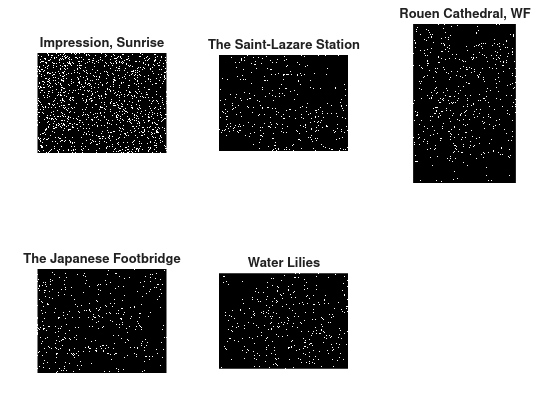

edge_list = cell(1,5);
for i = 1:length(gs_list)
    edge_list{i} = edge(imgaussfilt(gs_list{i}, 10), 'Canny');
end

figure;
t6 = tiledlayout(2,3, 'Padding', 'compact');
for i = 1:length(edge_list)
    nexttile;
    imshow(edge_list{i});
    title(image_title(i));
end

　　関数imgaussfiltの値を1~10までの間で調整してみたが、出力される結果は専らノイズじみた法則性を確認できない画像であった。ただし、画像をみると確認できるとおり、初期の絵には連続的な黒い領域が小さく点在しているのに対し、1877~1899年の絵には黒く大きな領域がいくつかあるのが確認できる。通常の絵や写真と異なり、エッジ検出がうまく行かなかったのは、異なる色を点として塗り続ける筆触分割というモネ特有の手法が影響したものと考えられる。これによって色の違いが数値上は些細な差として映る一方、人間が遠目でみるとはっきりとした風景がとして写るようになった。

#### 　7.3. 画像エントロピーの計算

　MATLABでサポートされているentropy()関数はグレースケール画像を渡すことにより、その画素値のばらつきを数値として返す。これを5作品のグレースケール画像に対し適応し、検証する。

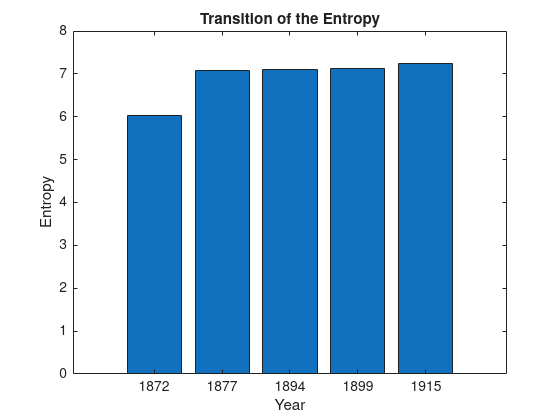

e = zeros(1,5);
for i = 1:length(gs_list)
    e(i) = entropy(gs_list{i});
end

figure;
bar(1:length(years),e);
xticks(1:length(years));
xticklabels(string(years));
xlabel("Year");
ylabel("Entropy");
title("Transition of the Entropy");

　得られた結果を確認してみると、最初の作品についてはEntropyが6近くで、それ以降に発表された作品では7の周辺の値をとっていることがわかる。この結果から、モネは晩年白内障を患っていたが、それでも使う色彩の複雑さには大きな影響をもたらしていないことがわかる。また、1877年以降の作品からEntropyの値が安定したことからも、1872年から1877年までの間で、モネの筆触分割の技術が完成したのだとも考察できる。

## 8. 参照元(References)

- [1]TRiCERA ART: "モネとは？有名絵画の「睡蓮」などの作品や生涯を解説", [https://www.tricera.net/ja/artclip/blog870?srsltid=AfmBOorZMHgXxNCElgcP1Noiem8abZCWZ84eUeh6WaiChV9Kt19l5DxL,](https://www.tricera.net/ja/artclip/blog870?srsltid=AfmBOorZMHgXxNCElgcP1Noiem8abZCWZ84eUeh6WaiChV9Kt19l5DxL,) 2025年11月28日参照